# One-dimensional linear basis functions

Construction of the linear one-dimensional basis functions (alternative known as hat basis functions) using the one-dimensional [Lagrange polynomials](https://en.wikipedia.org/wiki/Lagrange_polynomial)

Go to [THIS](matlab:open('./main_Chapter1_BasisFunctions.mlx')) Section in the main driver script *One-dimensional linear basis functions*

Go to [NEXT](matlab:open('./main_Chapter12_OneDimensionalQuadraticBasisFunctions.mlx')) Section *One-dimensional quadratic basis functions*

**Author: Dr.-Ing. Andreas Apostolatos**

**Date: 22.12.2022**

## Preamble

vars = ["X0L1" "XLL1" "numElementsL1" "mshL1"];
str = "This mlx-file should be run from parent mlx-file ..." + ...
    "main_Chapter01_OneDimensionalLinearBasisFunctions.mlx";
for ii = 1:length(vars)
    if ~exist(vars(ii), 'var') 
        error(strcat("Variable ", vars(ii), " is not defined. ", str));
    end
end

## Definition of the linear Lagrange Polynomials

The [Lagrange Polynomials](https://en.wikipedia.org/wiki/Lagrange_polynomial) are defined in one-dimension as follows:


$$l_j(x) = \prod_{1 \le m \le k, m \neq j} \frac{x - x_m}{x_j - x_m}$$


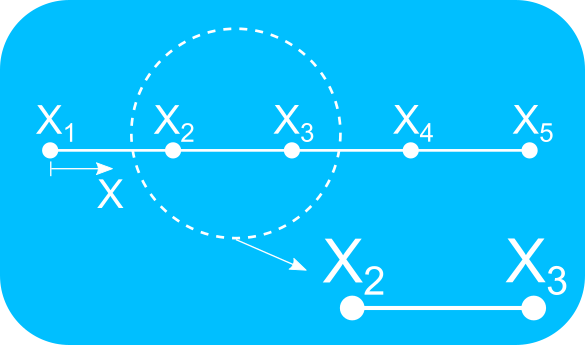

syms l1L1(X, X1, X2) l2L1(X, X1, X2)
l1L1(X, X1, X2) = (X - X2)/(X1 - X2);
l2L1(X, X1, X2) = (X - X1)/(X2 - X1);

## Visualization of the one-dimensional linear Lagrange Polynomials in the physical space of  the mesh

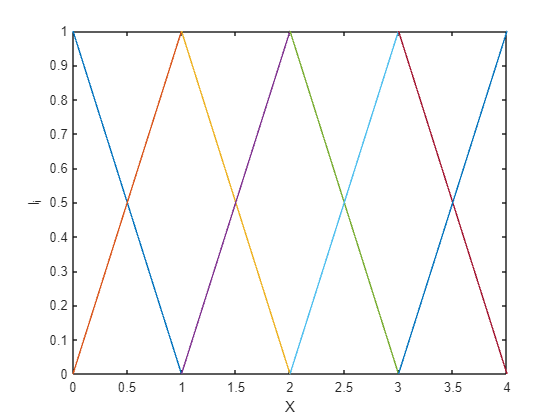

for ii = 1: length(mshL1.elements(:, 1))
    nodesEl = mshL1.nodes(mshL1.elements(ii, :));
    fplot([l1L1(X, nodesEl(1, 1), nodesEl(2, 1)) l2L1(X, nodesEl(1, 1), nodesEl(2, 1))], ...
        [nodesEl(1, 1), nodesEl(2, 1)]);
    if ii == 1
        hold on;
    end
end
xlabel("X")
ylabel("l_i")
hold off;

## Computation of the Lagrange polynomials in the parametric space

The parametric space of each element in this case is defined as $\xi \in [-1, 1]$:

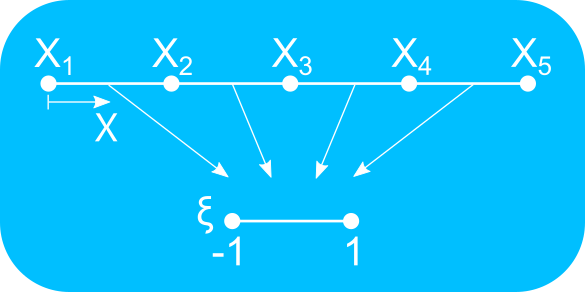

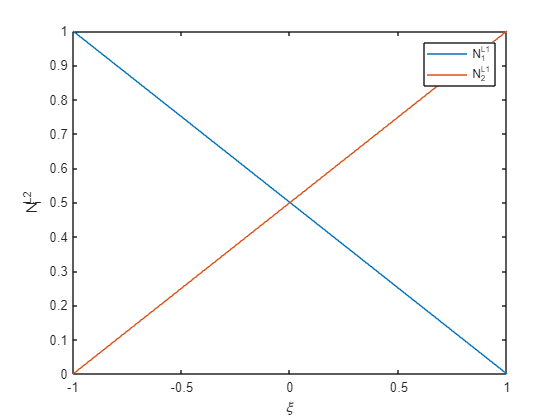

syms xi N1L1(xi) N2L1(xi) N(xi)
N1L1(xi) = l1L1(xi, -1, +1);
N2L1(xi) = l2L1(xi, -1, +1);
NL1(xi) = [N1L1(xi) N2L1(xi)];
fplot([N1L1 N2L1], [-1 +1])
legend(["N_1^{L1}", "N_2^{L1}"]);
xlabel("\xi")
ylabel("N_i^{L2}")

 **Reflect**

All elements in the finite element mesh share the same parametric space